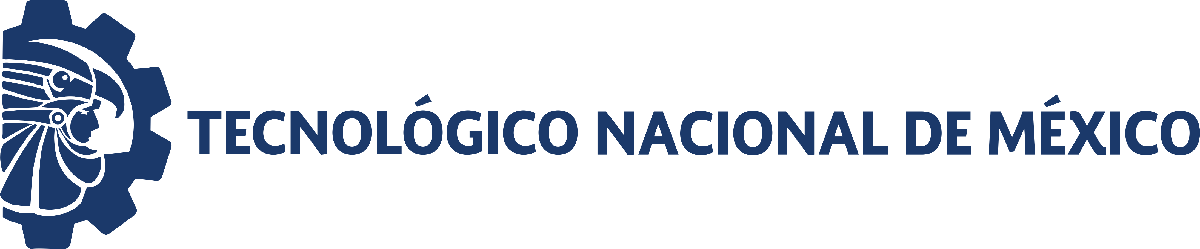                                 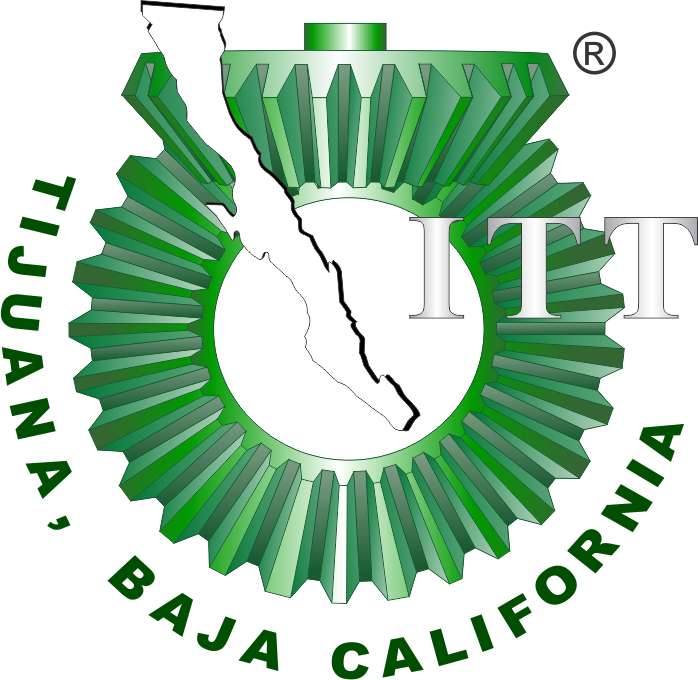

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

# Práctica 1: Sistema presa-depredador de Lotka-Volterra

**Objetivo. ** Aplicar el sistema de Lotka-Volterra para analizar los datos registrados en la interacción de dos especies articas, liebres (presa) y linces (depredador) durante 20 años. El sistema presa-depredador se formula mediante las siguientes dos EDOs de primer orden:


$$\dot x = \alpha x - \beta xy
$$



$$\dot y = \delta xy - \gamma y$$


donde los valores de los parámetros $\alpha$,$\beta ,$$\delta ,$$\gamma >0$, y las condiciones iniciales $x\left(0\right),$$y\left(0\right)>0$.

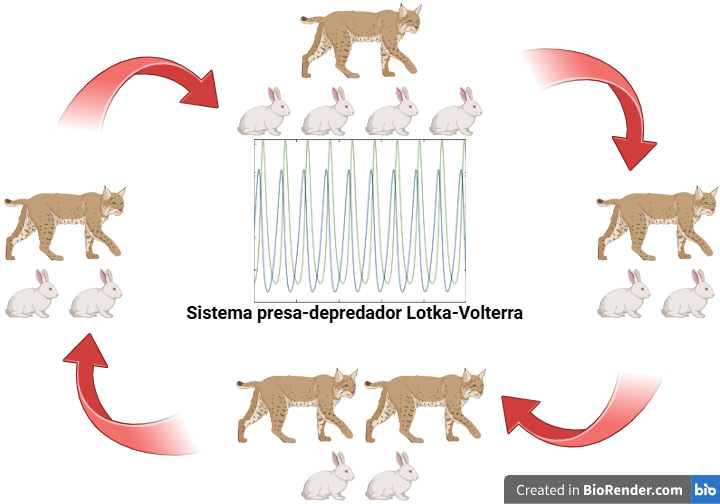 

Figura. Generar la figura del sistema presa-depredador con [https://bioart.niaid.nih.gov/](https://bioart.niaid.nih.gov/) o [https://www.biorender.com/](https://www.biorender.com/).

## Referencias

[1] Valle, Paul A., Syllabus para Biología de Sistemas y Gemelos Digitales, Tecnológico Nacional de México / Instituto Tecnológico de Tijuana, Tijuana, B.C., México, 2026. Permalink: [https://biomath.xyz/course/](https://biomath.xyz/course/) 

[2] Garfinkel, Alan, Jane Shevtsov, and Yina Guo. Modeling life: the mathematics of biological systems. Springer International Publishing AG, 2017.

## Información general

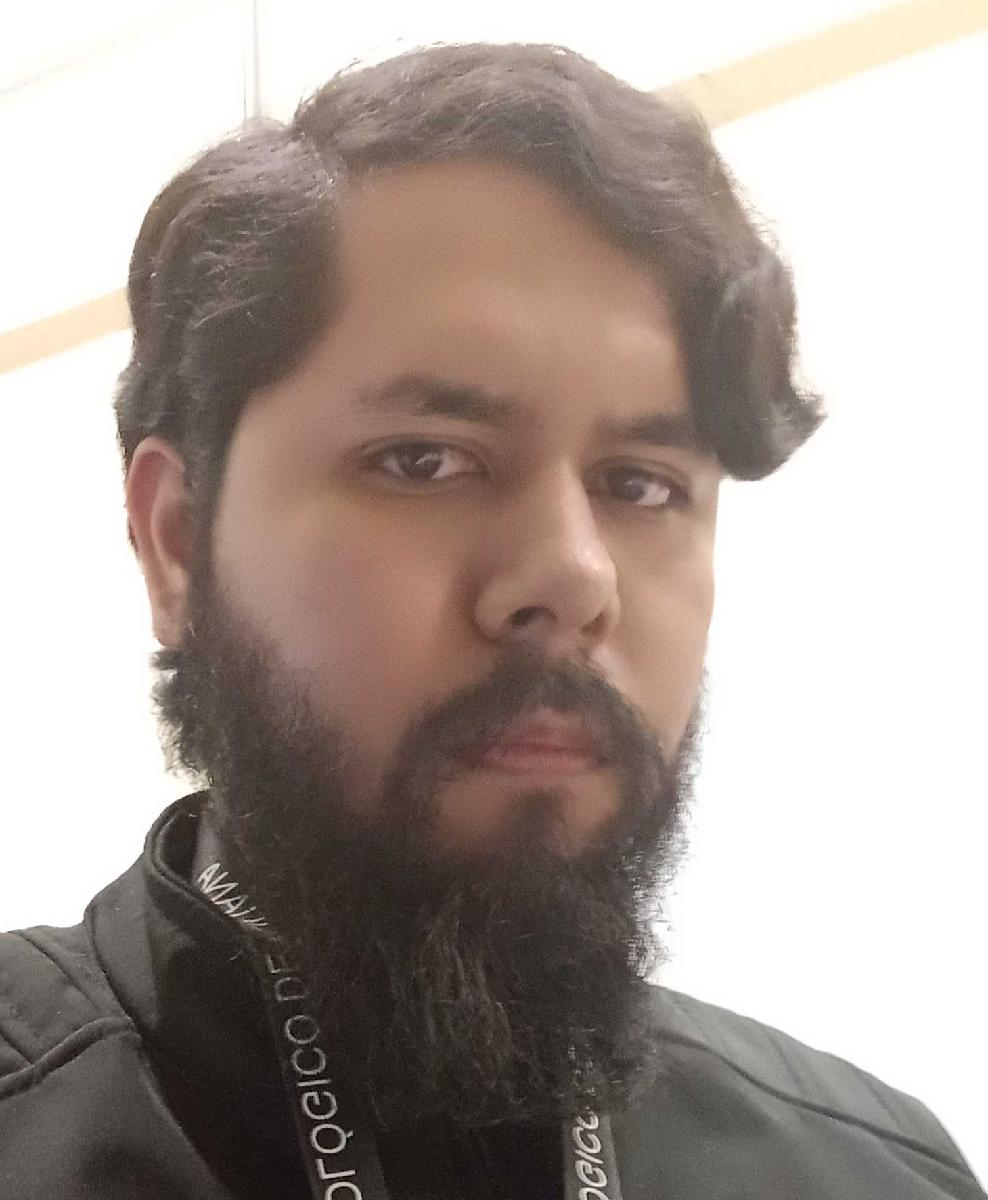

Nombre del alumno: **Vincent Alejandro Villela Salinas**

Número de control: **M25210045**

Correo institucional: **M25210045@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

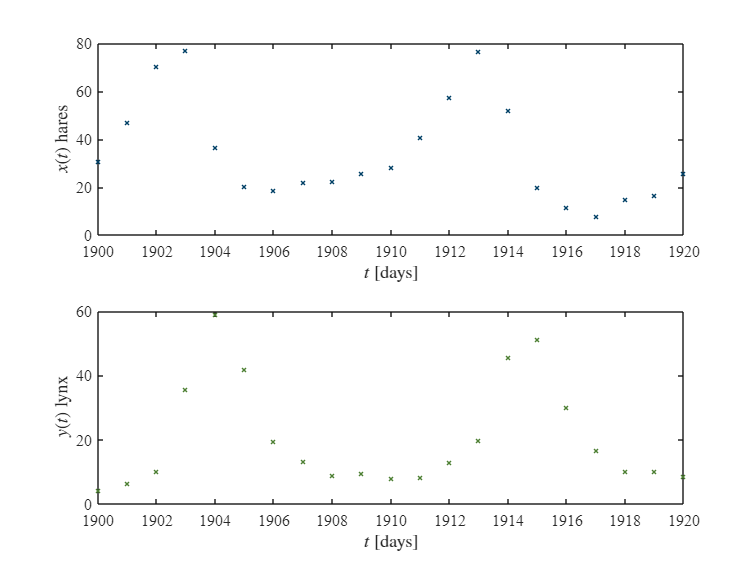

clc; clear; close all; warning('off','all')
sys = readmatrix('data.csv');
to = round(sys(:,1));
xo = sys(:,2);
yo = sys(:,3);
plotsys(to,xo,yo); exportgraphics(gcf,'data_raw.pdf','ContentType','vector')

## Procesamiento de datos

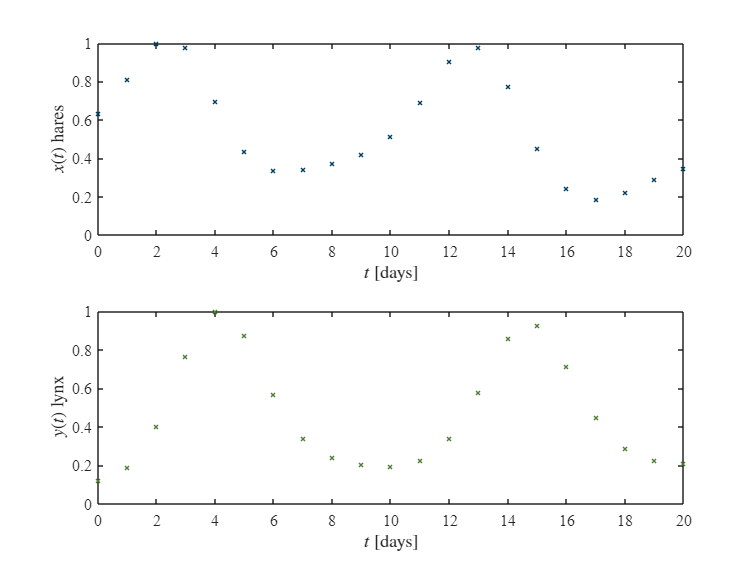

xo = smoothdata(xo,'gaussian',5); xo = xo/max(xo);
yo = smoothdata(yo,'gaussian',5); yo = yo/max(yo);
to = to - to(1);
plotsys(to,xo,yo); exportgraphics(gcf,'data_raw.pdf','ContentType','vector')

### Datos suavizados

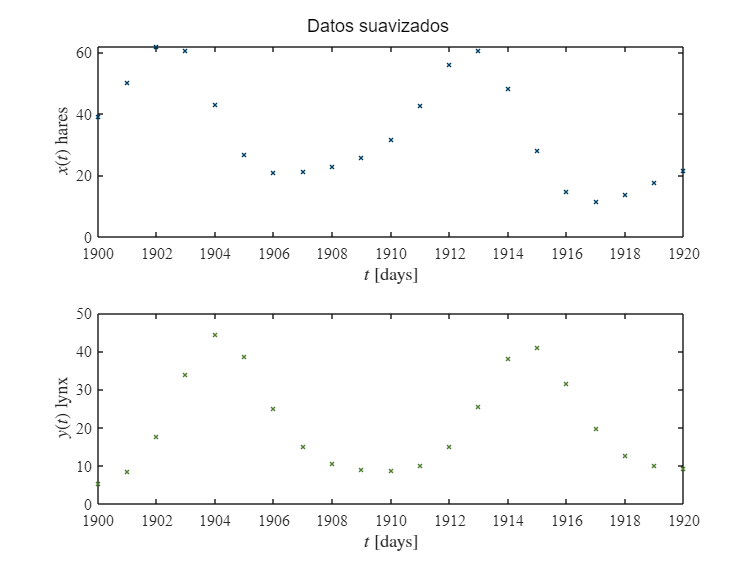

smooth = true; normalize = false;
[to,xo,yo] = getdata('data.csv',smooth,normalize);
plotsys(to,xo,yo); sgtitle('Datos suavizados');...
    exportgraphics(gcf,'data_smooth.pdf','ContentType','vector')

### Datos normalizados

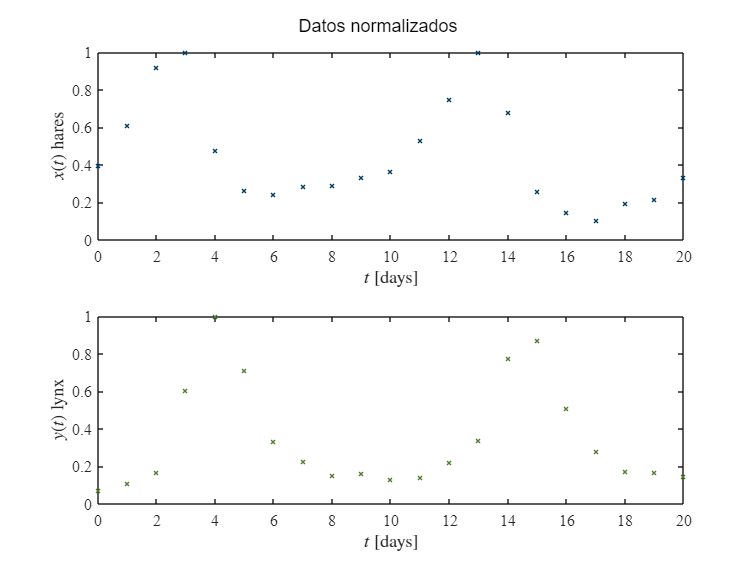

smooth = false; normalize = true;
[to,xo,yo] = getdata('data.csv',smooth,normalize);
plotsys(to,xo,yo); sgtitle('Datos normalizados');...
    exportgraphics(gcf,'data_normalized.pdf','ContentType','vector')

### Datos suavizados y normalizados

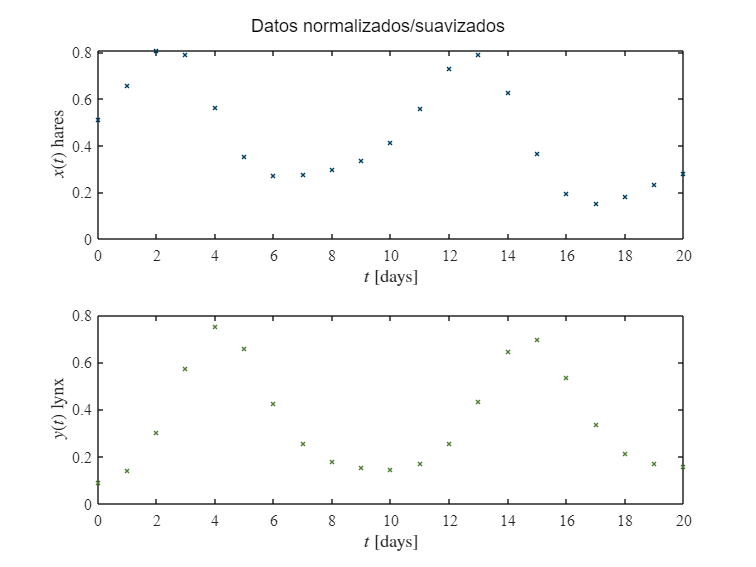

smooth = true; normalize = true;
[to,xo,yo] = getdata('data.csv',smooth,normalize);
plotsys(to,xo,yo); sgtitle('Datos normalizados/suavizados');...
    exportgraphics(gcf,'data_smooth_normalized.pdf','ContentType','vector')

## Regresión no lineal

clear; close all
smooth = false; normalize = true;
[to,xo,yo] = getdata('data.csv',smooth,normalize);
Po=[0.6;1.2;1.5;0.8]; biostats = true;
mdl = Variant(to,xo,yo,Po,biostats);

Degrees of freedom: 38
t-student value: 2.0244
Significance value (alpha): 0.05
 
    Parameters     Estimate       SE         MoE              CI95             Pvalue  
    ___________    ________    ________    ________    __________________    __________

    {["alpha"]}    0.55095     0.024549    0.049697    0.50125    0.60064    1.5811e-23
    {["beta" ]}     1.6527     0.094096     0.19049     1.4622     1.8432    7.8512e-20
    {["delta"]}      2.018     0.092986     0.18824     1.8298     2.2062    5.1729e-23
    {["gamma"]}    0.82983      0.03826    0.077454    0.75238    0.90728    5.2831e-23

R-cuadrada ordinaria: 0.95092
R-cuadrada ajustada: 0.94705
Suma residual de cuadrados: 0.15718
Criterio de información de Akaike: -107.506
Criterio de información de Akaike ajustado (n

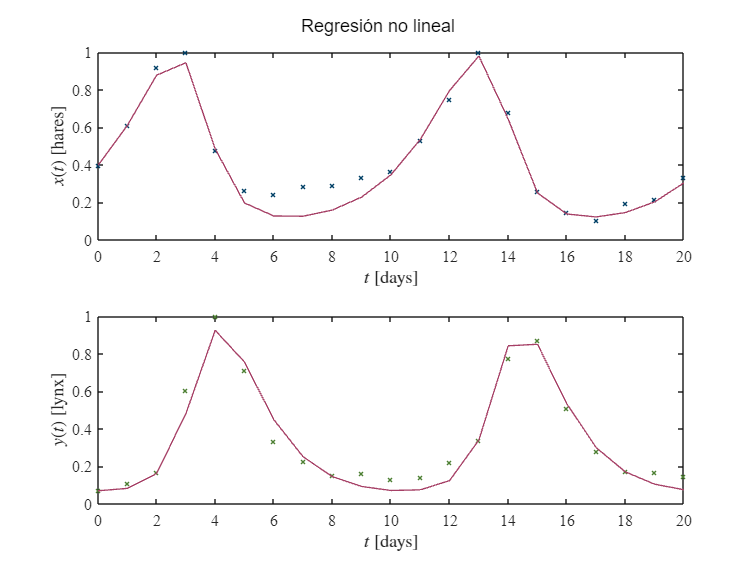

fa = mdl.Fitted;
fa = reshape(fa,[],2);
xa = fa(:,1); ya = fa(:,2);
plotresults(to,xo,yo,to,xa,ya); sgtitle('Regresión no lineal');...
    exportgraphics(gcf,'data_nonlinear_regresion.pdf','ContentType','vector')

## Predicción del modelo a 2t

clear; close all
smooth = false; normalize = true;
[to,xo,yo] = getdata('data.csv',smooth,normalize);
Po=[0.6;1.2;1.5;0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po,biostats);
par = table2array(mdl.Coefficients(:,1))

par =     0.5509
    1.6527
    2.0180
    0.8298


alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);
x0 = xo(1); y0 = yo(1); tend = to(end); dt = 0.001;

### Método de Heun

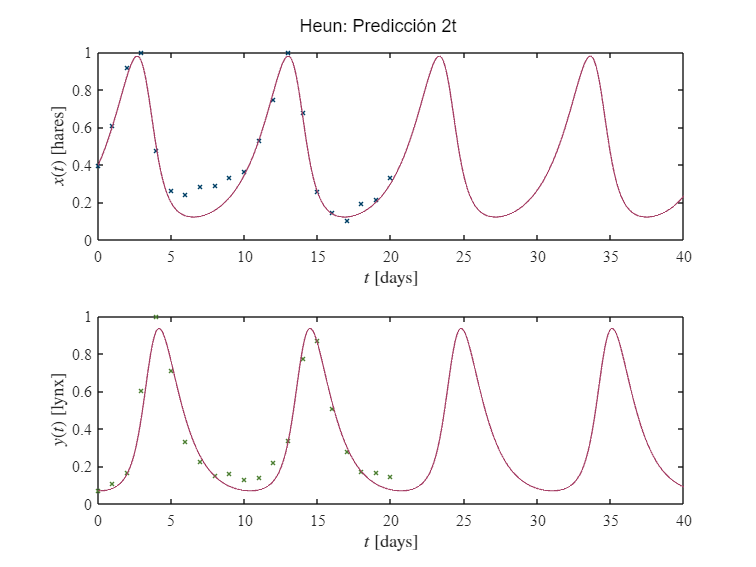

[th,xh,yh] = sysheun(x0,y0,alpha,beta,delta,gamma,2*tend,dt);
plotresults(to,xo,yo,th,xh,yh); sgtitle('Heun: Predicción 2t');...
    exportgraphics(gcf,'data_heun_prediction.pdf','ContentType','vector')

### Método de euler

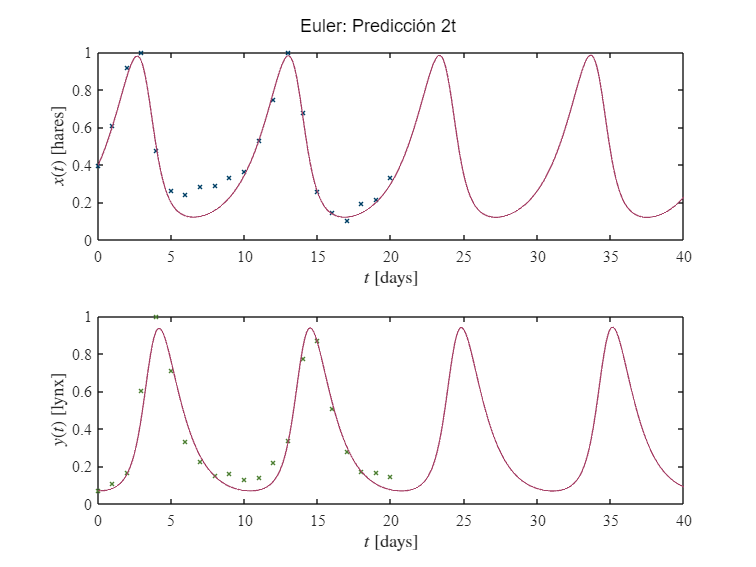

[te,xe,ye] = syseuler(x0,y0,alpha,beta,delta,gamma,2*tend,dt);
plotresults(to,xo,yo,te,xe,ye); sgtitle('Euler: Predicción 2t');...
    exportgraphics(gcf,'data_euler_prediction.pdf','ContentType','vector')

## Puntos de equilibrio

clc; clear
syms x y alpha beta delta gamma
dx_dt = alpha*x - beta*x*y == 0;
dy_dt = delta*x*y -gamma*y == 0;
fxy = solve([dx_dt,dy_dt],[x,y]);
fprintf(['Puntos de equilibrio del sistema: ',num2str(length(fxy.x))]);...
fprintf(['Puntos de equilibrio del sistema: ',num2str(length(fxy.y))]);

Puntos de equilibrio del sistema: 2

Puntos de equilibrio del sistema: 2

xe_1 = fxy.x(1); ye_1 = fxy.y(1);
xe_2 = fxy.x(2); ye_2 = fxy.y(2);
fprintf('Puntos de equilibrio simbolicos: ');...
    disp([xe_1,ye_1;xe_2,ye_2])

Puntos de equilibrio simbolicos: 

$$\left(\begin{array}{cc} 0 & 0\\ \frac{\gamma }{\delta } & \frac{\alpha }{\beta } \end{array}\right)$$

## Soluciones y trayectoria

clear; close all
smooth = false; normalize = true;
[to,xo,yo] = getdata('data.csv',smooth,normalize);
Po=[0.6;1.2;1.5;0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po,biostats);
par = table2array(mdl.Coefficients(:,1))

par =     0.5509
    1.6527
    2.0180
    0.8298


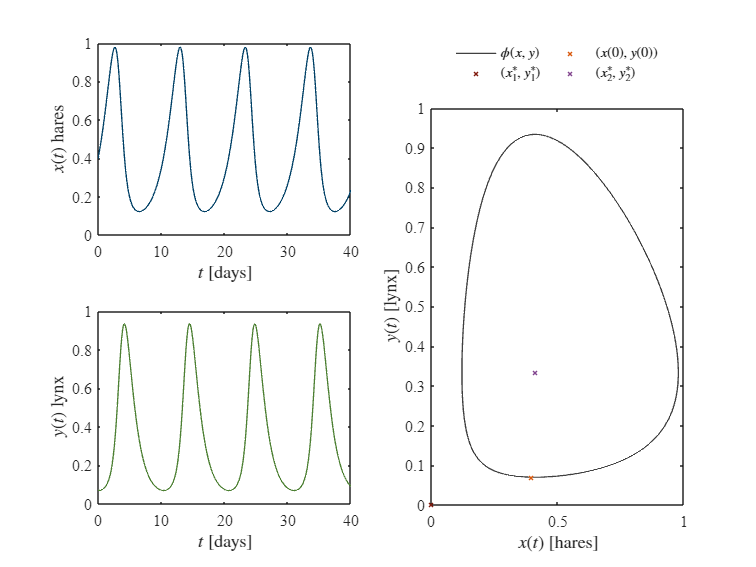

alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);
x0 = xo(1); y0 = yo(1); tend = to(end); dt = 0.001;
[th,xh,yh] = sysheun(x0,y0,alpha,beta,delta,gamma,2*tend,dt);
plotedos(th,xh,yh,par); exportgraphics(gcf,'phase_plane.pdf','ContentType','vector')

### Trayectorias/soluciones positivamente invariantes

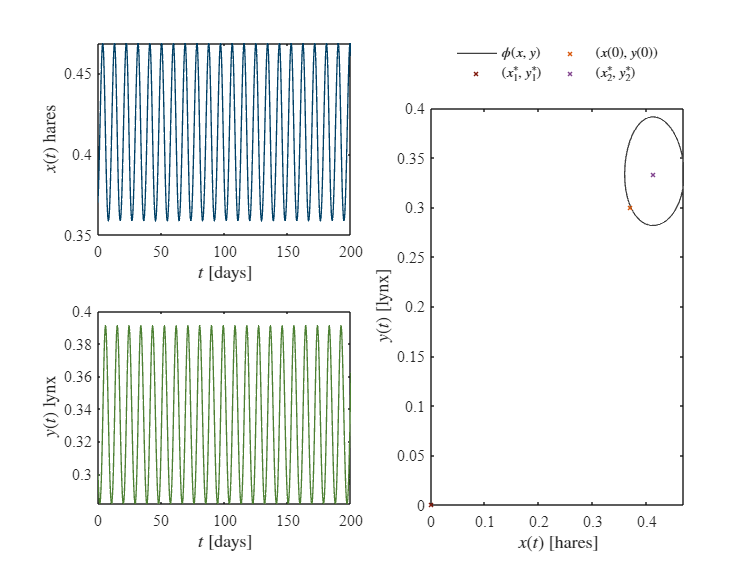

alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);
x0 = gamma/delta-(gamma/delta)*0.1; y0 = alpha/beta-(alpha/beta)*0.1; tend = 100; dt = 1E-3;
[th,xh,yh] = sysheun(x0,y0,alpha,beta,delta,gamma,2*tend,dt);
plotedos(th,xh,yh,par);

### Influencia de dt en la aproximación de las soluciones: Euler

clear; close all
smooth = false; normalize = true;
[to,xo,yo] = getdata('data.csv',smooth,normalize);
Po=[0.5;1.6;1.9;0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po,biostats);
par = table2array(mdl.Coefficients(:,1))

par =     0.5509
    1.6527
    2.0180
    0.8298


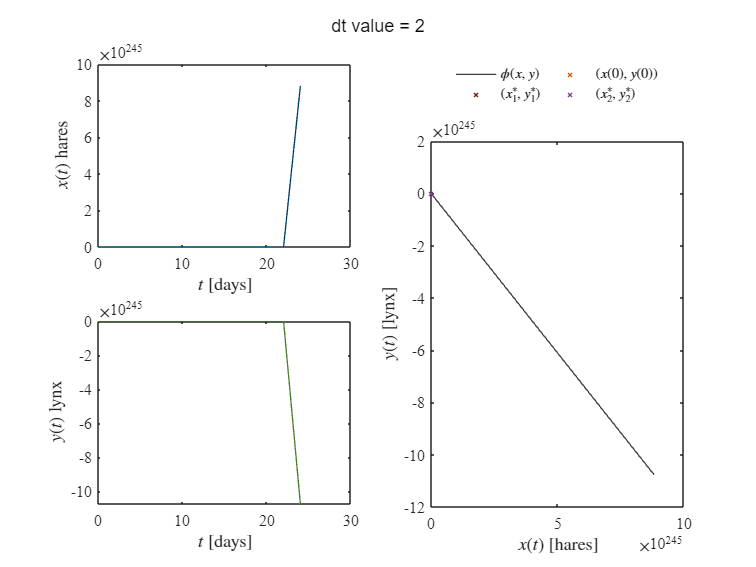

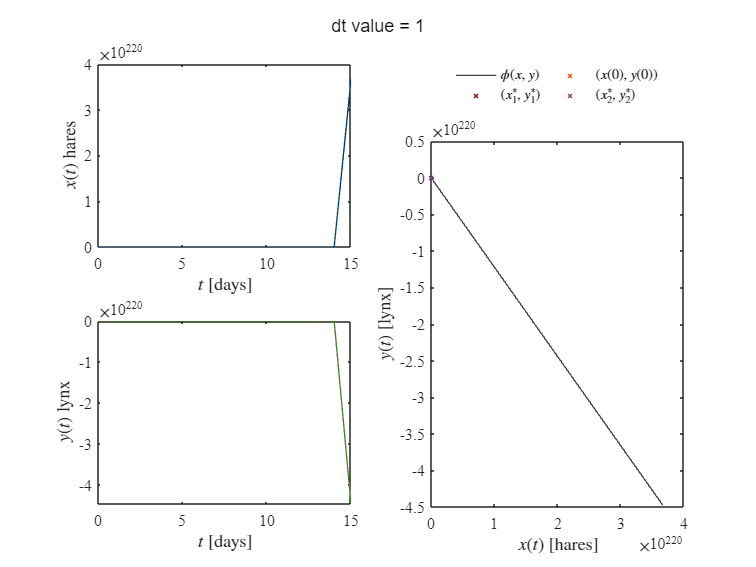

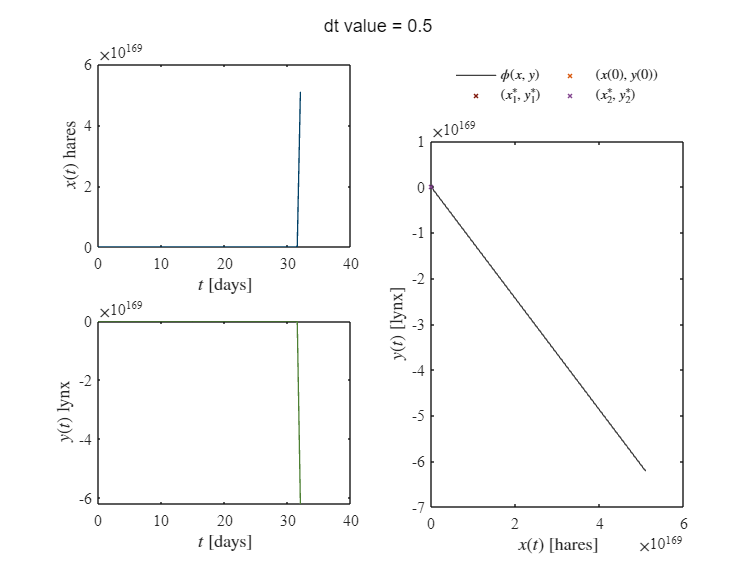

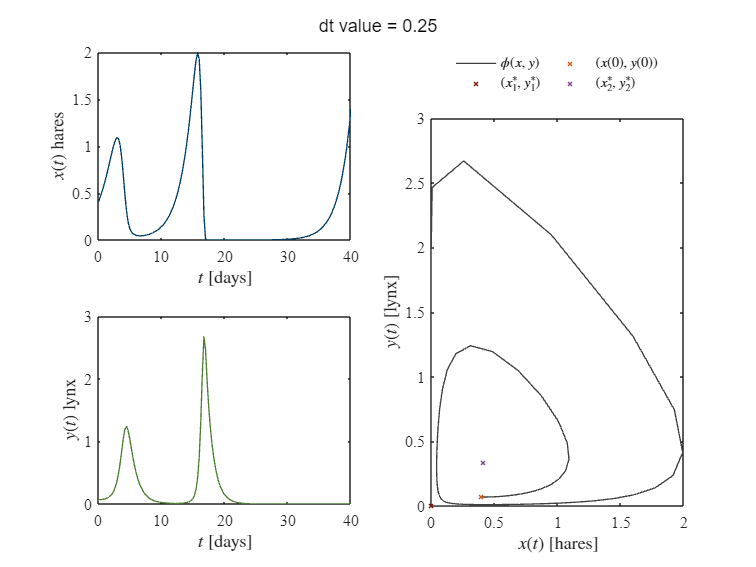

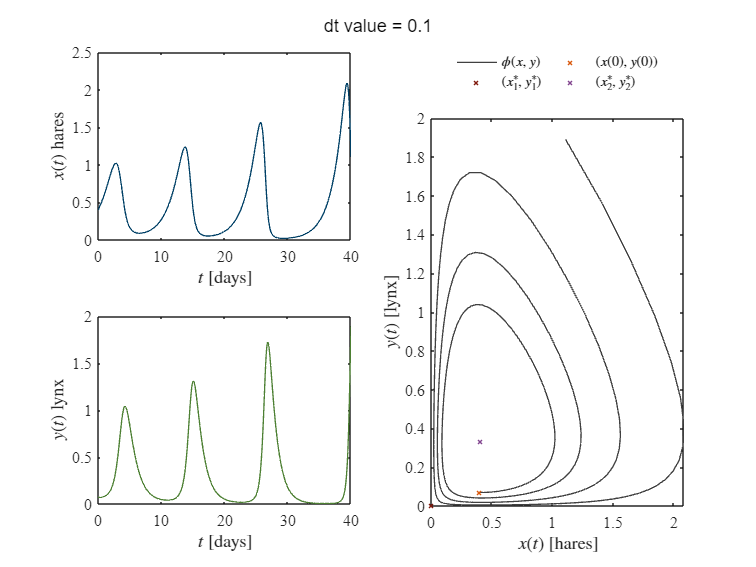

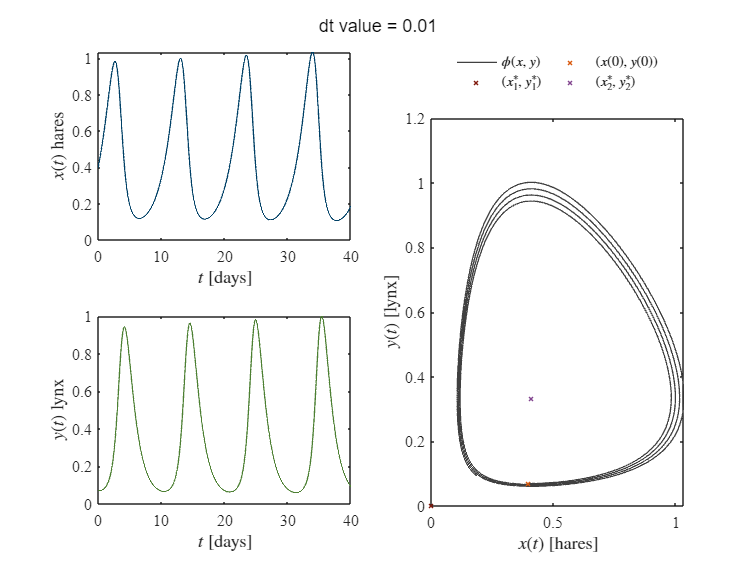

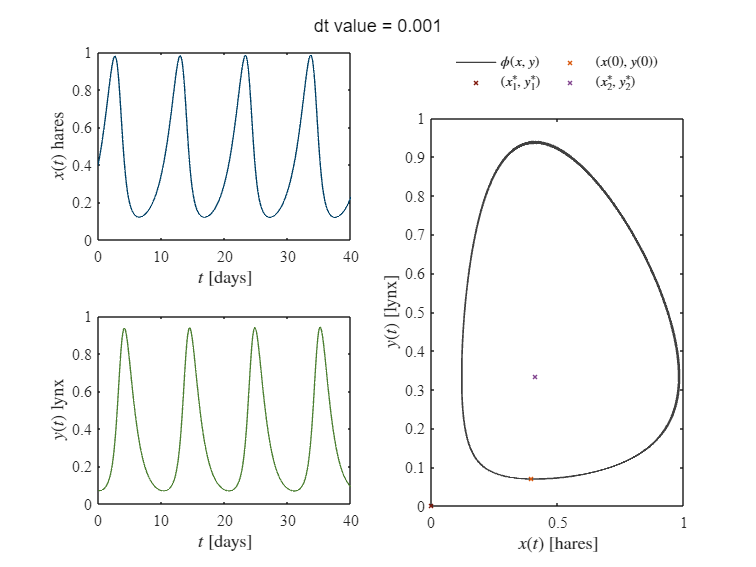

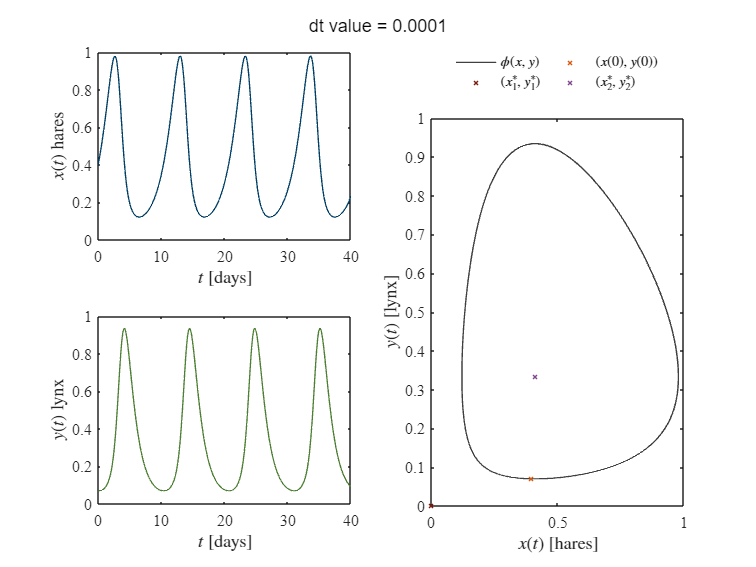

alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);
x0 = xo(1); y0 = yo(1); tend = to(end); dt = 0.001;
dt = [2;1;0.5;0.25;0.1;1E-2;1E-3;1E-4;1E-5;1E-6;1E-7];
for i = 1:length(dt)
    [te,xe,ye] = syseuler(x0,y0,alpha,beta,delta,gamma,2*tend,dt(i));
    plotedos(te,xe,ye,par); sgtitle(['dt value = ',num2str(dt(i))]);...
    exportgraphics(gcf,['euler dt ',num2str(dt(i)),'.pdf'],'ContentType','vector')
end

### Influencia de dt en la aproximación de las soluciones: Heun

clear; close all
smooth = false; normalize = true;
[to,xo,yo] = getdata('data.csv',smooth,normalize);
Po=[0.5;1.6;1.9;0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po,biostats);
par = table2array(mdl.Coefficients(:,1))

par =     0.5509
    1.6527
    2.0180
    0.8298


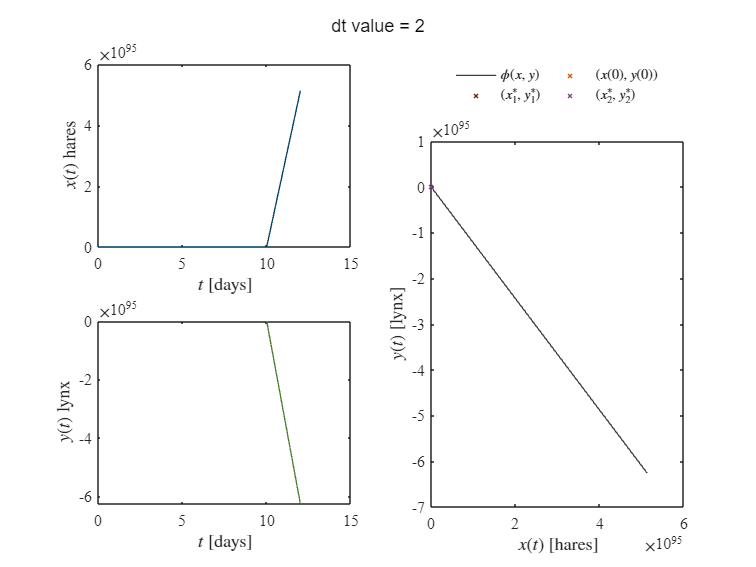

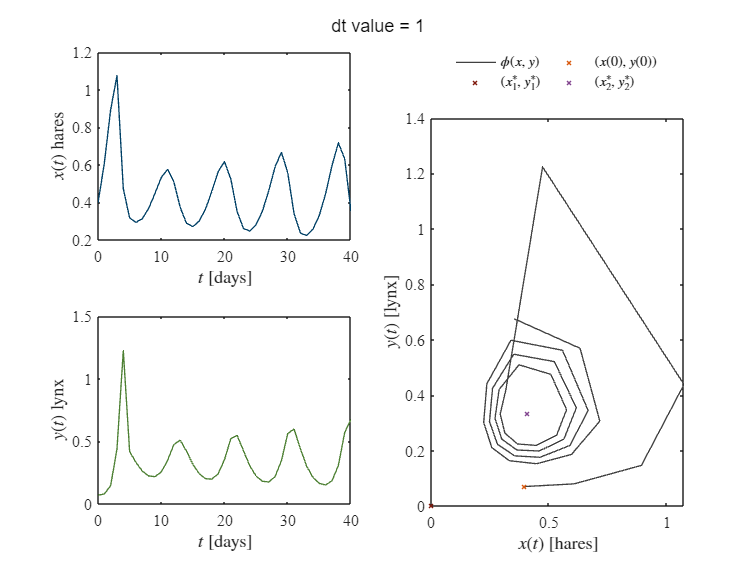

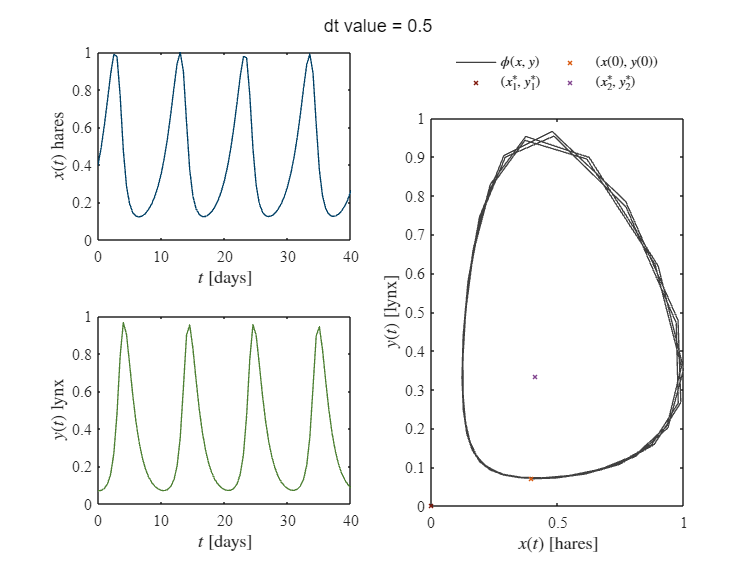

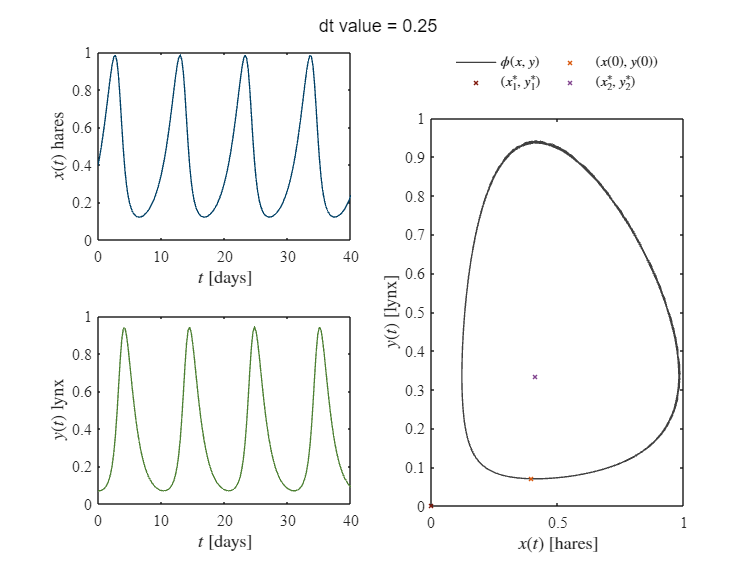

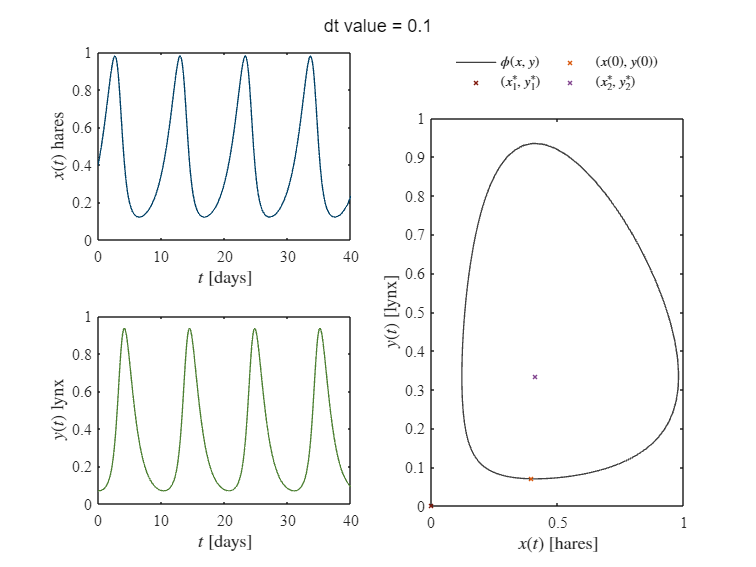

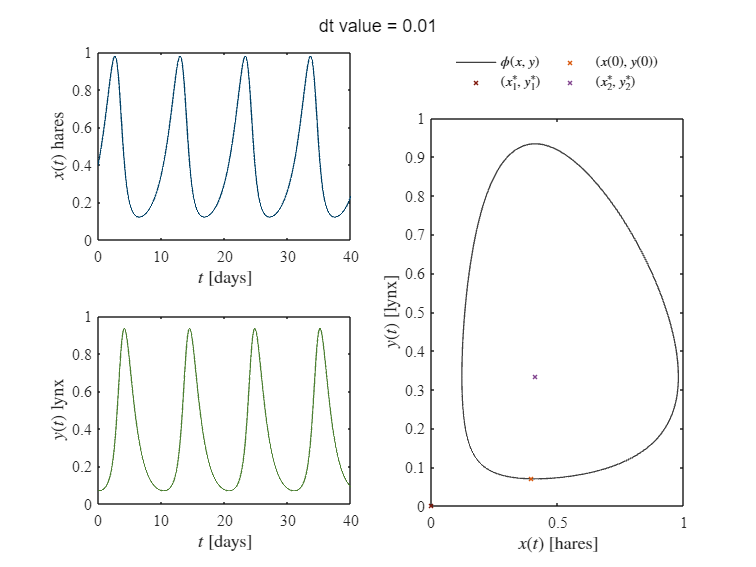

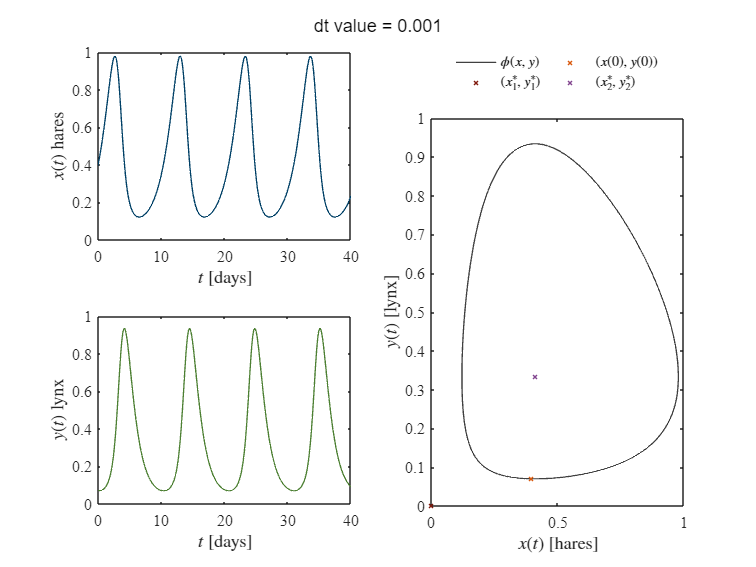

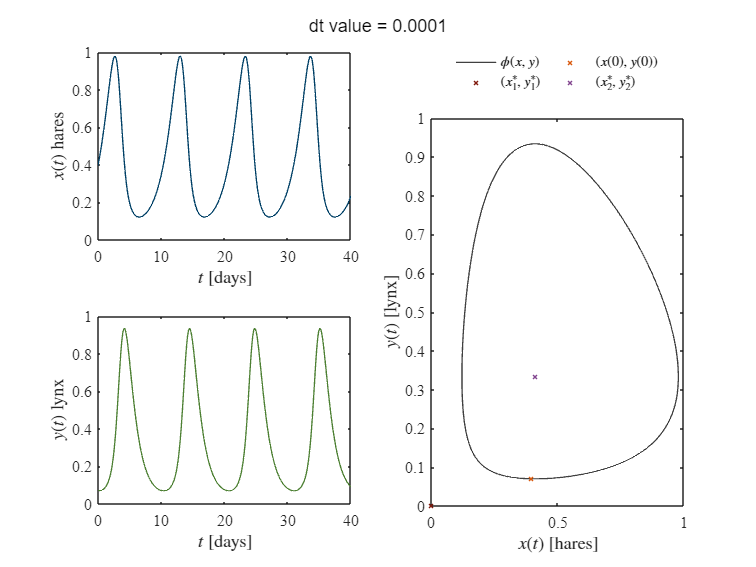

alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);
x0 = xo(1); y0 = yo(1); tend = to(end); dt = 0.001;
dt = [2;1;0.5;0.25;0.1;1E-2;1E-3;1E-4;1E-5;1E-6;1E-7];
for i = 1:length(dt)
    [th,xh,yh] = sysheun(x0,y0,alpha,beta,delta,gamma,2*tend,dt(i));
    plotedos(th,xh,yh,par); sgtitle(['dt value = ',num2str(dt(i))]);...
    exportgraphics(gcf,['heun dt ',num2str(dt(i)),'.pdf'],'ContentType','vector')
end

### Soluciones/trayectorias positivamente invariantes

clear; close all
smooth = false; normalize = true;
[to,xo,yo] = getdata('data.csv',smooth,normalize);
Po=[0.5;1.6;1.9;0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po,biostats);
par = table2array(mdl.Coefficients(:,1))

par =     0.5509
    1.6527
    2.0180
    0.8298


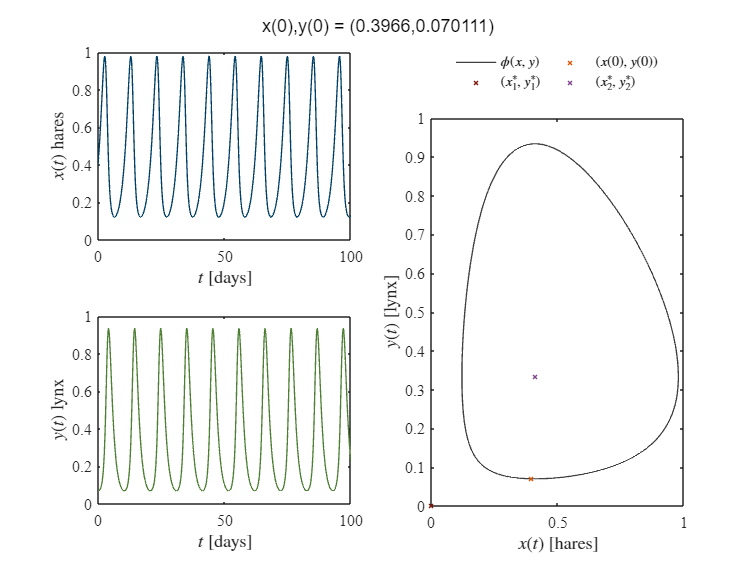

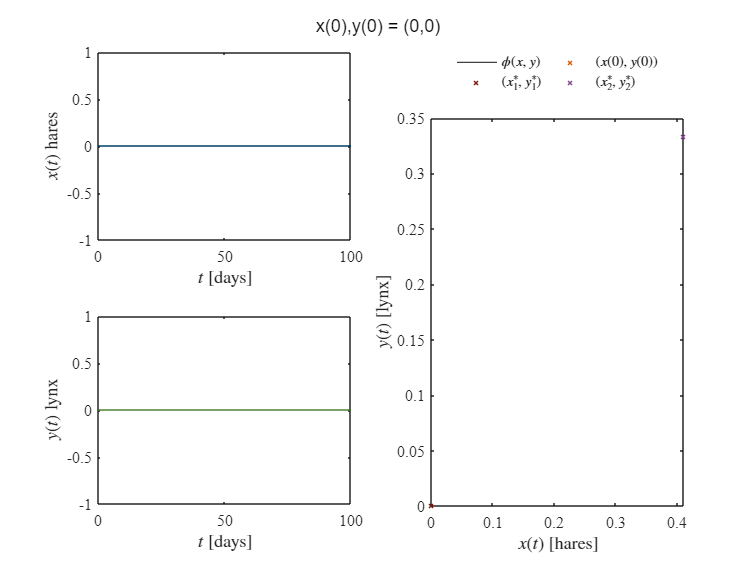

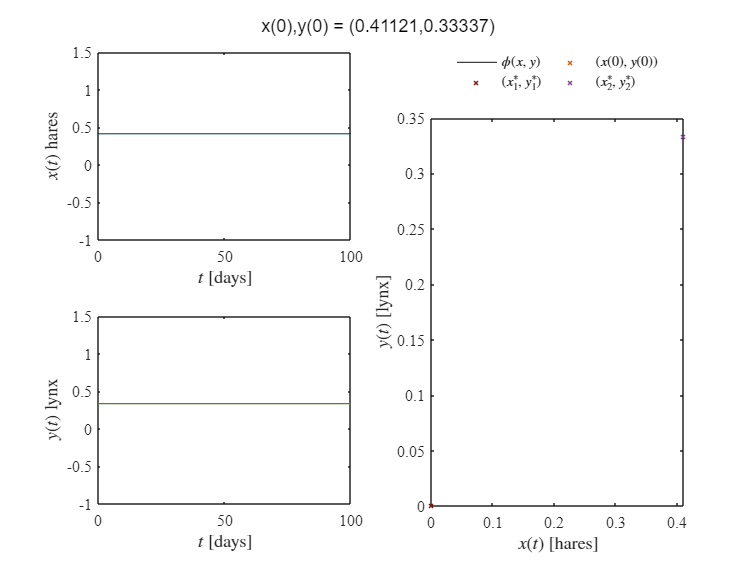

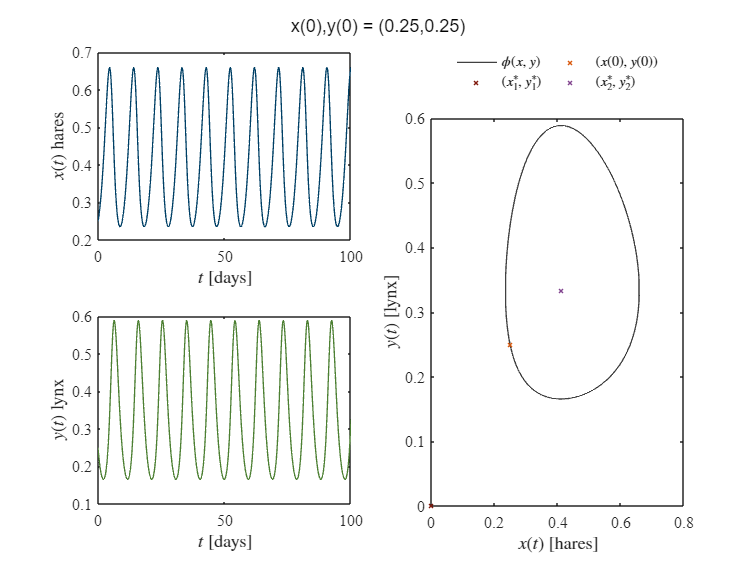

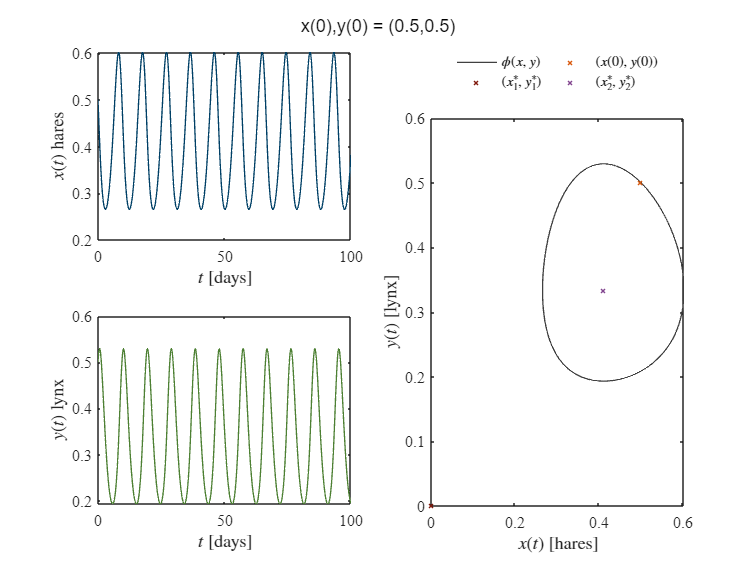

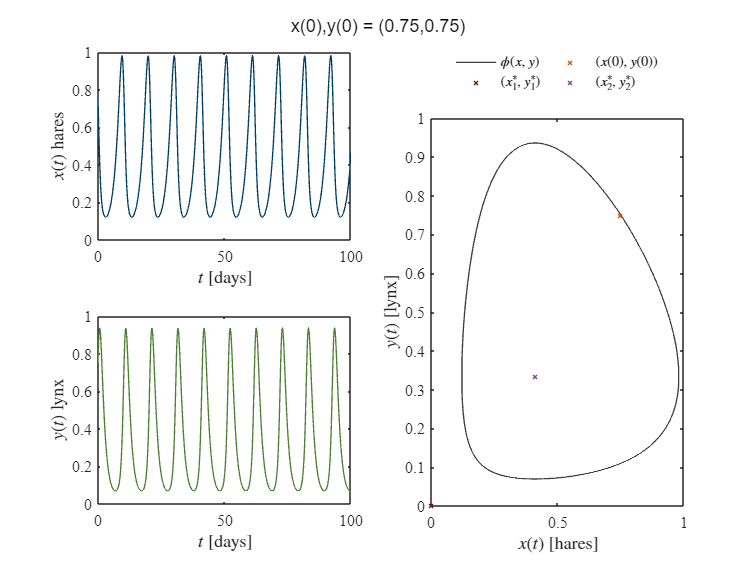

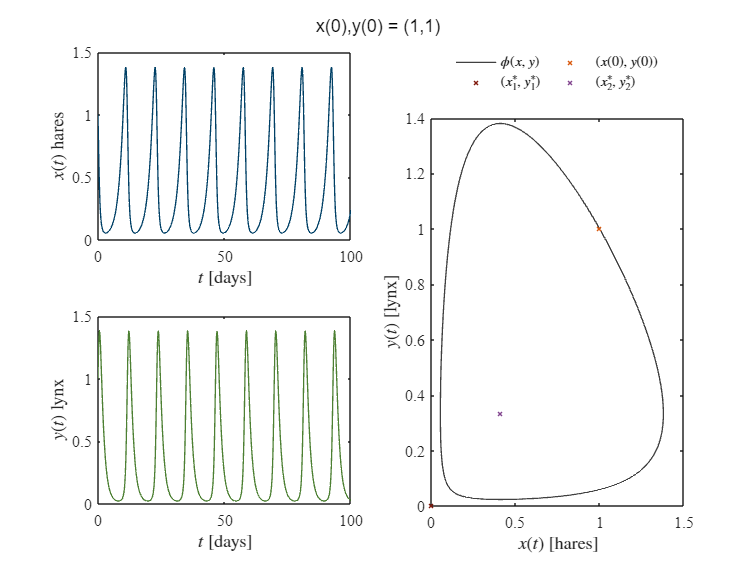

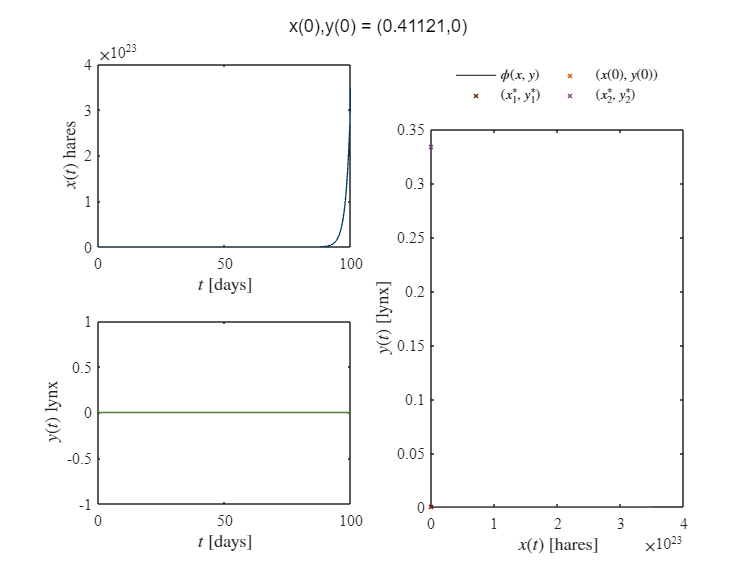

alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);
tend = to(end); dt = 0.001;
x0 = [xo(1),0,gamma/delta,0.25,0.5,0.75,1,gamma/delta,0         ,alpha/beta ,-0.1, 0.1,-0.1,0.001,0.001,1    ,1]; 
y0 = [yo(1),0,alpha/beta ,0.25,0.5,0.75,1,0          ,alpha/beta,gamma/delta, 0.1,-0.1,-0.1,0.001,1    ,0.001,1];
for i = 1:length(x0)
    [t,x,y] = sysheun(x0(i),y0(i),alpha,beta,delta,gamma,5*tend,dt);
    plotedos(t,x,y,par); sgtitle(['x(0),y(0) = (',num2str(x0(i)),',',num2str(y0(i)),')']);...
        exportgraphics(gcf,['initial_conditions ',num2str((i)),'.pdf'],'ContentType','vector')
end

## Simulink

clear; close all
smooth = false; normalize = true;
[to,xo,yo] = getdata('data.csv',smooth,normalize);
Po=[0.5;1.6;1.9;0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po,biostats);
par = table2array(mdl.Coefficients(:,1))

par =     0.5509
    1.6527
    2.0180
    0.8298


file = 'Lotka_Volterra';
sim(file);
parameters.StopTime = '100';

### odes para soluciones *stiff*

#### Función ode15s

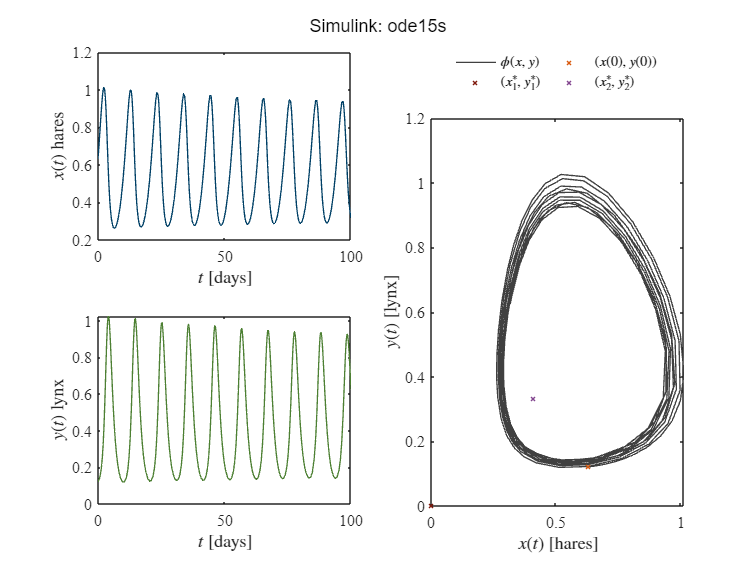

parameters.Solver = 'ode15s';
%parameters.MaxStep = '0.1';
f = sim(file,parameters);
plotedos(f.t,f.x,f.y,par); sgtitle('Simulink: ode15s');...
    exportgraphics(gcf,'simulink_ode15s.pdf','ContentType','vector')

#### Función ode23s

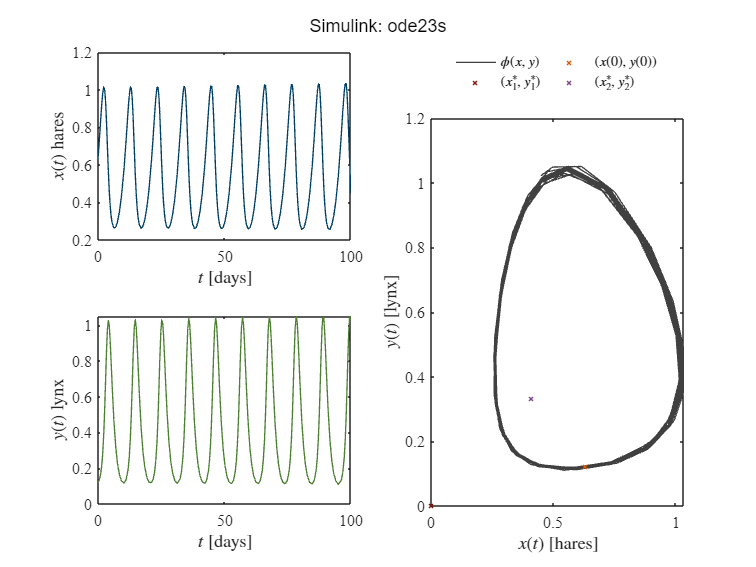

parameters.Solver = 'ode23s';
% parameters.MaxStep = '0.1';
f = sim(file,parameters);
plotedos(f.t,f.x,f.y,par); sgtitle('Simulink: ode23s');...
    exportgraphics(gcf,'simulink_ode23s.pdf','ContentType','vector')

#### Función ode23t

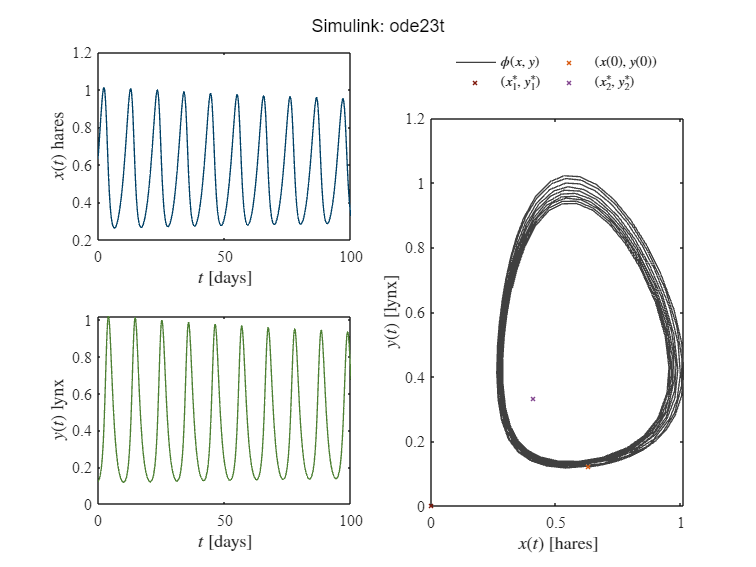

parameters.Solver = 'ode23t';
% parameters.MaxStep = '0.1';
f = sim(file,parameters);
plotedos(f.t,f.x,f.y,par); sgtitle('Simulink: ode23t');...
    exportgraphics(gcf,'simulink_ode23t.pdf','ContentType','vector')

#### Función ode23tb

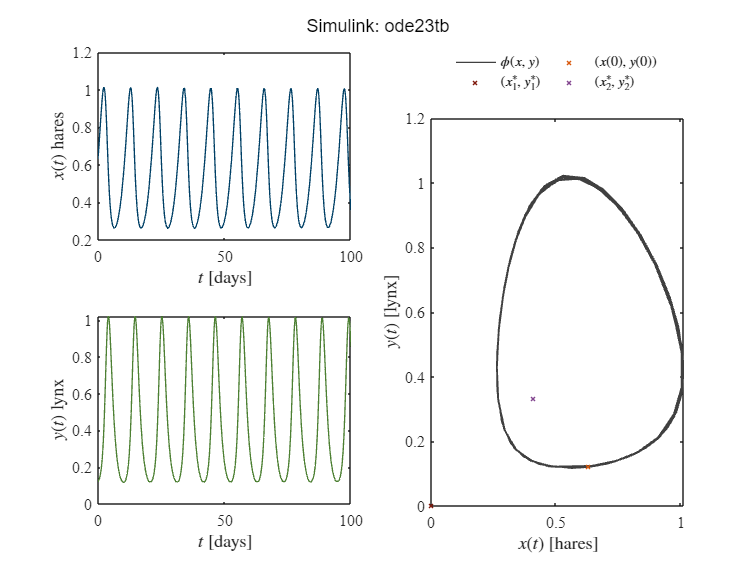

parameters.Solver = 'ode23tb';
% parameters.MaxStep = '0.1';
f = sim(file,parameters);
plotedos(f.t,f.x,f.y,par); sgtitle('Simulink: ode23tb');...
    exportgraphics(gcf,'simulink_ode23tb.pdf','ContentType','vector')

### odes para soluciones *nostiff*

#### Función ode45

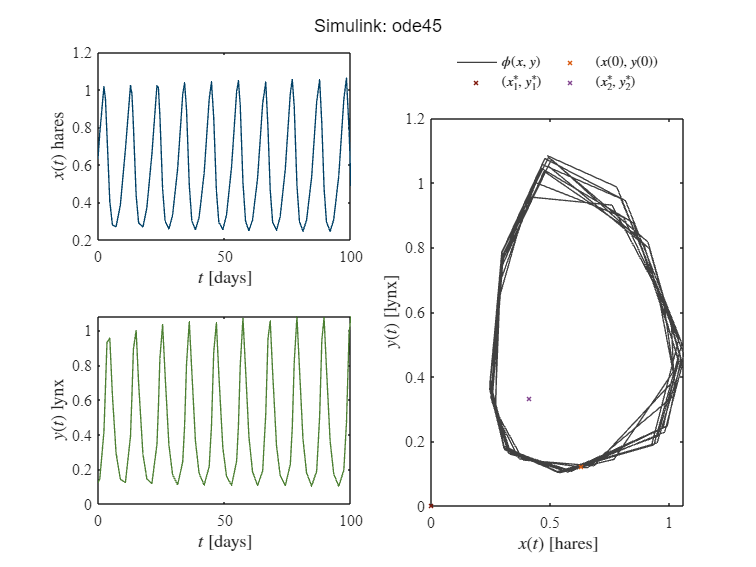

parameters.Solver = 'ode45';
% parameters.MaxStep = '0.1';
f = sim(file,parameters);
plotedos(f.t,f.x,f.y,par); sgtitle('Simulink: ode45');...
    exportgraphics(gcf,'simulink_ode45.pdf','ContentType','vector')

#### Función ode23

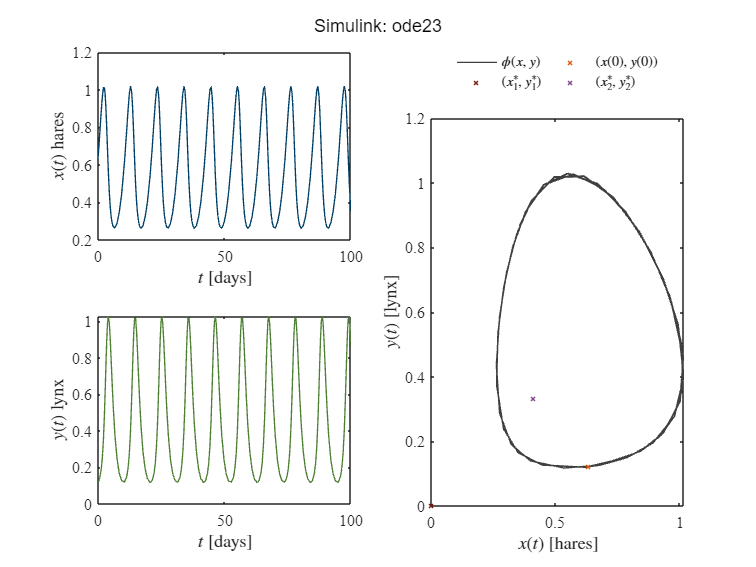

parameters.Solver = 'ode23';
% parameters.MaxStep = '0.1';
f = sim(file,parameters);
plotedos(f.t,f.x,f.y,par); sgtitle('Simulink: ode23');...
    exportgraphics(gcf,'simulink_ode23.pdf','ContentType','vector')

#### Función ode113

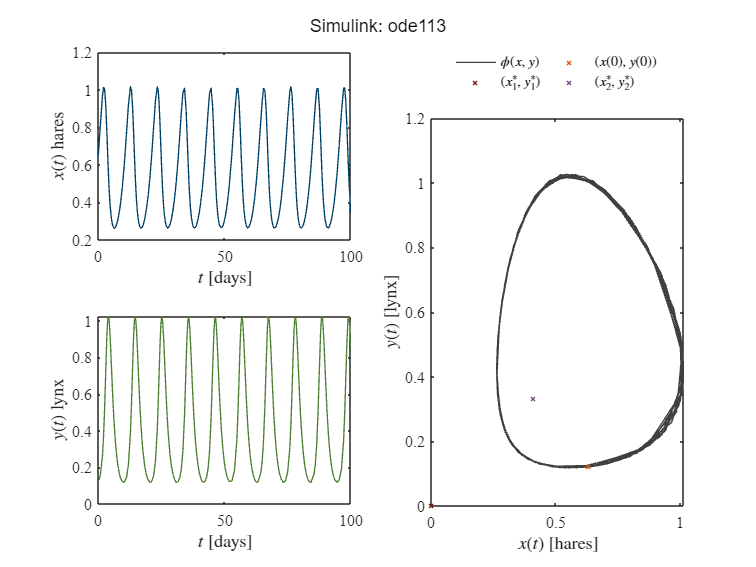

parameters.Solver = 'ode113';
% parameters.MaxStep = '0.1';
f = sim(file,parameters);
plotedos(f.t,f.x,f.y,par); sgtitle('Simulink: ode113');...
    exportgraphics(gcf,'simulink_ode113.pdf','ContentType','vector')

#### Ode23 con paso máximo

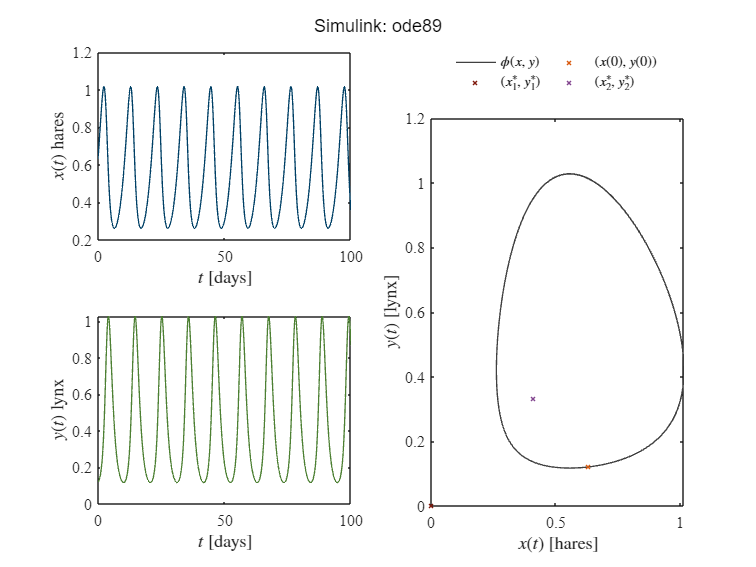

parameters.Solver = 'ode23';
parameters.MaxStep = '0.1';
f = sim(file,parameters);
plotedos(f.t,f.x,f.y,par); sgtitle('Simulink: ode89');...
    exportgraphics(gcf,'simulink_ode89.pdf','ContentType','vector')

#### Función ode1

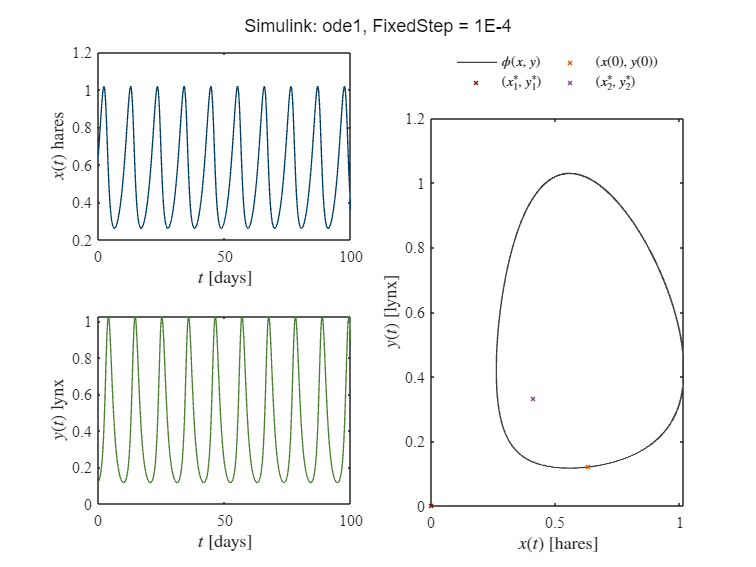

parameters.Solver = 'ode1';
parameters.FixedStep = '1E-4';
f = sim(file,parameters);
plotedos(f.t,f.x,f.y,par); sgtitle('Simulink: ode1, FixedStep = 1E-4');...
    exportgraphics(gcf,'simulink_ode1.pdf','ContentType','vector')

#### Función ode2

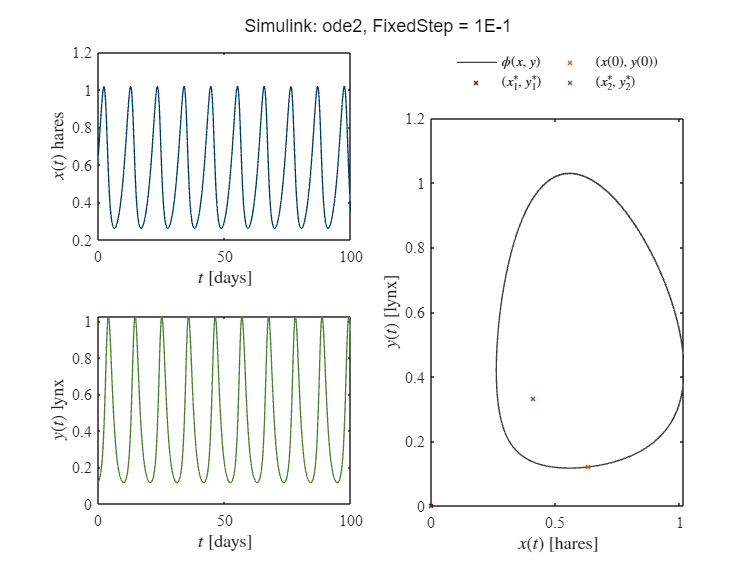

parameters.Solver = 'ode2';
parameters.FixedStep = '1E-1';
f = sim(file,parameters);
plotedos(f.t,f.x,f.y,par); sgtitle('Simulink: ode2, FixedStep = 1E-1');...
    exportgraphics(gcf,'simulink_ode2.pdf','ContentType','vector')

#### Función ode3

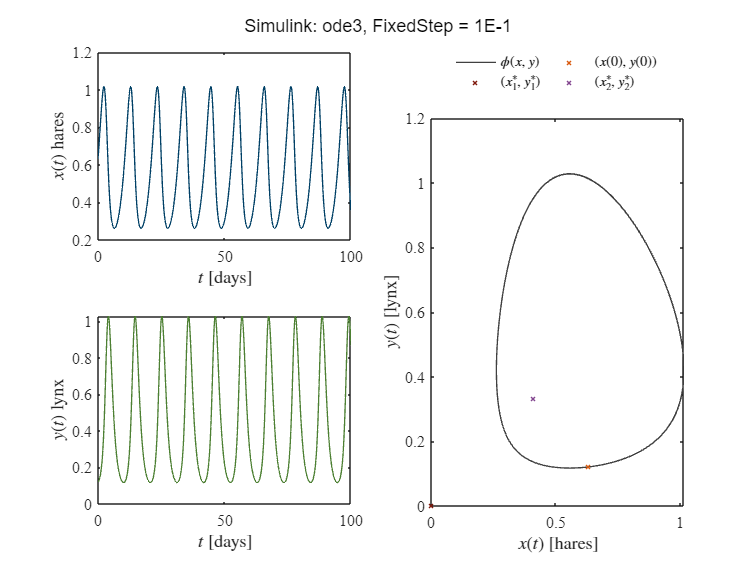

parameters.Solver = 'ode3';
parameters.FixedStep = '1E-1';
f = sim(file,parameters);
plotedos(f.t,f.x,f.y,par); sgtitle('Simulink: ode3, FixedStep = 1E-1');...
    exportgraphics(gcf,'simulink_ode3.pdf','ContentType','vector')

#### Función ode4

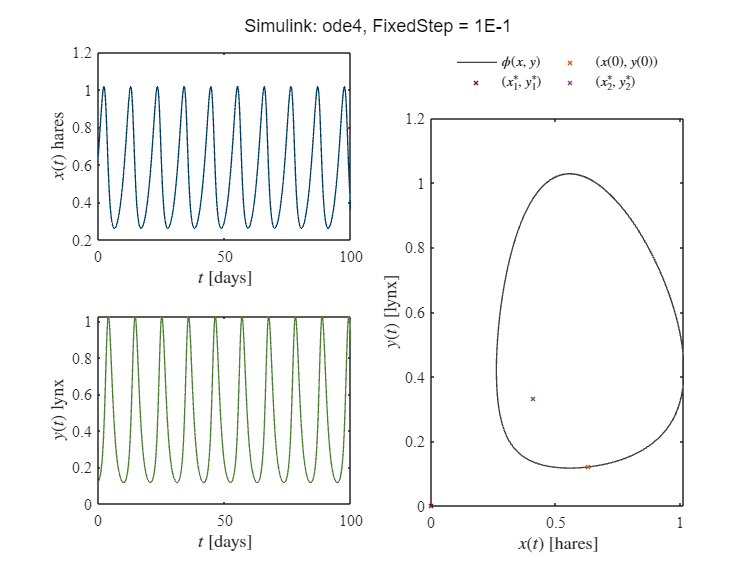

parameters.Solver = 'ode4';
parameters.FixedStep = '1E-1';
f = sim(file,parameters);
plotedos(f.t,f.x,f.y,par); sgtitle('Simulink: ode4, FixedStep = 1E-1');...
    exportgraphics(gcf,'simulink_ode4.pdf','ContentType','vector')

#### Función ode5

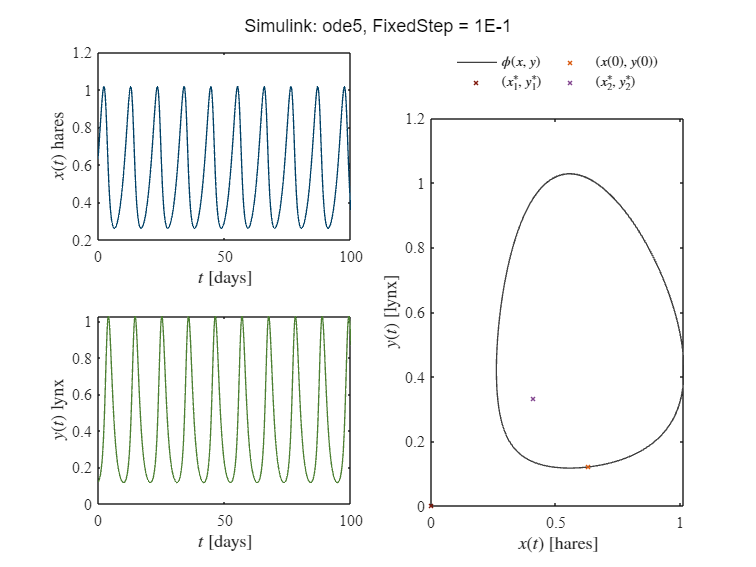

parameters.Solver = 'ode5';
parameters.FixedStep = '1E-1';
f = sim(file,parameters);
plotedos(f.t,f.x,f.y,par); sgtitle('Simulink: ode5, FixedStep = 1E-1');...
    exportgraphics(gcf,'simulink_ode5.pdf','ContentType','vector')

### Funciones odes

clear; close all
smooth = false; normalize = true;
[to,xo,yo] = getdata('data.csv',smooth,normalize);
Po=[0.5;1.6;1.9;0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po,biostats);
par = table2array(mdl.Coefficients(:,1))
x0 = xo(1); y0 = yo(1);
[t,solV] = ode89(@(t,V) sysODE(V,par),[0,100],[x0,y0]);
x = solV(:,1);
y = solV(:,2);
plotedos(t,x,y,par); sgtitle('Simulink: ode89, tspan variable');...
    exportgraphics(gcf,'simulink_ode89.pdf','ContentType','vector')
dt = 1E-3;
tspan = (0:dt:100)';
[ti,solVi] = ode89(@(t,V) sysODE(V,par),tspan,[x0,y0]);
xi = solVi(:,1);
yi = solVi(:,2);
plotedos(ti,xi,yi,par); sgtitle('Simulink: ode89, tspan fijo');...
    exportgraphics(gcf,'simulink_ode89_tspan.pdf','ContentType','vector')

## Predicción con los datos experimentales

clear; close all
smooth = false; normalize = true;
[to,xo,yo] = getdata('data.csv',smooth,normalize);
tend = to(end);

Po=[0.5;1.6;1.9;0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po,biostats);
par = table2array(mdl.Coefficients(:,1))

par =     0.5509
    1.6527
    2.0180
    0.8298


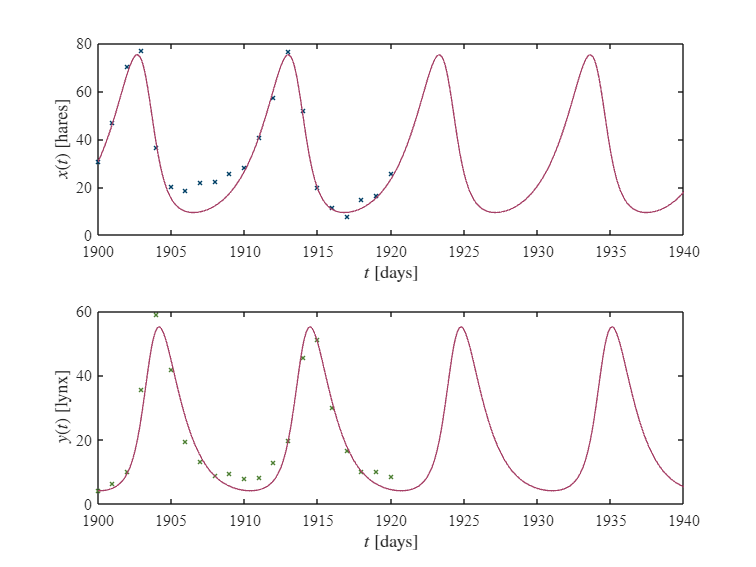

alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);

smooth = false; normalize = false;
[to,xo,yo] = getdata('data.csv',smooth,normalize);
betat = beta/max(yo); deltat = delta/max(xo);
dt = 1E-1; x0 = xo(1); y0 = yo(1);

[t,x,y] = sysheun(x0,y0,alpha,betat,deltat,gamma,2*tend,dt);
plotresults(to,xo,yo,t+to(1),x,y)

## Funciones

### Soluciones y trayectoria en el plano de fase

function plotsys(to,xo,yo)
    set(figure(),'Color','w')
    FS = 12;
    set(gcf,'Units','Centimeters','Position',[1,1,20,15])
    subplot(2,1,1)
    hold on; box on; grid off;
    plot(to,xo,'x','LineWidth',1,'MarkerSize',4,'Color',[0,0.25,0.4])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$x(t)$ hares','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    subplot(2,1,2)
    hold on; box on; grid off;
    plot(to,yo,'x','LineWidth',1,'MarkerSize',4,'Color',[0.3,0.5,0.2])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$y(t)$ lynx','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
end

function plotresults(t,xo,yo,ta,xa,ya)
    set(figure(),'Color','w')
    FS = 12;
    set(gcf,'Units','Centimeters','Position',[1,1,20,15])
    subplot(2,1,1)
    hold on; box on; grid off;
    plot(t,xo,'x','LineWidth',1,'MarkerSize',4,'Color',[0,0.25,0.4])
    plot(ta,xa,'-','LineWidth',1,'MarkerSize',4,'Color',[0.65,0.25,0.4])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$x(t)$ [hares]','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    subplot(2,1,2)
    hold on; box on; grid off;
    plot(t,yo,'x','LineWidth',1,'MarkerSize',4,'Color',[0.3,0.5,0.2])
    plot(ta,ya,'-','LineWidth',1,'MarkerSize',4,'Color',[0.65,0.25,0.4])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$y(t)$ [lynx]','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
end

function plotedos(t,x,y,P)
    set(figure(),'Color','w')
    FS = 12;
    set(gcf,'Units','Centimeters','Position',[1,1,20,15])
    subplot(2,2,1)
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'MarkerSize',4,'Color',[0,0.25,0.4])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$x(t)$ hares','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    subplot(2,2,3)
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1,'MarkerSize',4,'Color',[0.3,0.5,0.2])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$y(t)$ lynx','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    subplot(2,2,[2 4])
    hold on; box on; grid off;
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
    plot(x,y,'-','LineWidth',1,'Color',[0.25,0.25,0.25])
    plot(x(1),y(1),'x','LineWidth',1,'MarkerSize',4,'Color',[0.85,0.35,0.05])
    plot(0,0,'x','LineWidth',1,'MarkerSize',4,'Color',[0.5,0.1,0.05])
    plot(gamma/delta,alpha/beta,'x','LineWidth',1,'MarkerSize',4,'Color',[0.51,0.27,0.56])
    L = legend('$\phi(x,y)$','$(x(0),y(0))$','$(x^*_1,y^*_1$)','$(x^*_2,y^*_2)$');
    set(L,'Interpreter','Latex','Location','NorthOutside','Orientation','Horizontal',...
        'Box','Off','NumColumns',2)
    % plot(x,y,'-','LineWidth',1,'MarkerSize',4,'Color',[0.65,0.2,0.2])
    xlabel('$x(t)$ [hares]','Interpreter','Latex','FontSize',FS)
    ylabel('$y(t)$ [lynx]','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
end

function dV = sysODE(V,par)
    alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);
    dV = zeros(2,1);
    dV(1) = alpha*V(1) - beta*V(1)*V(2);
    dV(2) = delta*V(1)*V(2) - gamma*V(2);
end

function [to,xo,yo] = getdata(file,smooth,normalize)
    sys = readmatrix(file);
    to = round(sys(:,1));
    xo = sys(:,2);
    yo = sys(:,3);
    if smooth == false && normalize == false
    return
    elseif smooth == true && normalize == false
        xo = smoothdata(xo,'gaussian',5);
        yo = smoothdata(yo,'gaussian',5);
    elseif smooth == false && normalize == true
        to = to - to(1);
        xo = xo/max(xo);
        yo = yo/max(yo);
    elseif smooth == true && normalize == true
        to = to - to(1);
        xo = xo/max(xo);
        yo = yo/max(yo);
        xo = smoothdata(xo,'gaussian',5);
        yo = smoothdata(yo,'gaussian',5);
    end
end

### Ajuste por regresión no lineal

function mdl = Variant(to,xo,yo,Po,biostats)
    x0 = xo(1); y0 = yo(1);
    t = [to;to];
    fo = [xo;yo];
    
    function fa = model(pa,ta)
        alpha = pa(1); beta = pa(2); delta = pa(3); gamma = pa(4);
        dt = 1E-1;
        time = (0:dt:max(ta))';
        x = zeros(length(time),1); x(1) = x0;
        y = zeros(length(time),1); y(1) = y0;
        n = round(max(ta)/dt);
        
        for i = 1:n %Metodo de Heun [Diferencias finitas]
            [fx,fy] = f(x(i),y(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            [fxn,fyn] = f(xn,yn);
            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
        end

        function [dx,dy] = f(x,y)
            dx = alpha*x - beta*x*y;
            dy = delta*x*y - gamma*y;
        end

        xi = interp1(time,x,to,'linear');
        yi = interp1(time,y,to,'linear');

        fa = [xi;yi];
    end

    mdl = fitnlm(t,fo,@model,Po);

    if biostats == true
        Estimate = table2array(mdl.Coefficients(:,1));
        SE = table2array(mdl.Coefficients(:,2));
        Pvalue = table2array(mdl.Coefficients(:,4));
        alpha = 0.05;
        CI95 = coefCI(mdl,alpha);
        dof = mdl.DFE;
        tval = tinv(1-alpha/2,dof);
        MoE = SE*tval;
        Parameters = {"alpha";"beta";"delta";"gamma"};
        Results = table(Parameters,Estimate,SE,MoE,CI95,Pvalue);
        disp(['Degrees of freedom: ',num2str(dof)])
        disp(['t-student value: ',num2str(tval)])
        disp(['Significance value (alpha): ',num2str(alpha)])
        disp(' '); disp(Results)
        R2o = mdl.Rsquared.Ordinary;
        R2a = mdl.Rsquared.Adjusted;
        SSE = mdl.SSE;
        AIC = mdl.ModelCriterion.AIC;
        AICc = mdl.ModelCriterion.AICc;
        fprintf(['R-cuadrada ordinaria: ', num2str(R2o)]);...
        fprintf(['\nR-cuadrada ajustada: ', num2str(R2a)]);...
        fprintf(['\nSuma residual de cuadrados: ', num2str(SSE)]);...
        fprintf(['\nCriterio de información de Akaike: ', num2str(AIC)]);...
        fprintf(['\nCriterio de información de Akaike ajustado (n/k<40): ', num2str(AICc)]);
    end
end

### Método de Euler

function [t,x,y] = syseuler(x0,y0,alpha,beta,delta,gamma,tend,dt)
    n = round(tend/dt);
    t = (0:dt:tend)';
    x = zeros(length(t),1); x(1) = x0;
    y = zeros(length(t),1); y(1) = y0;

    for i = 1:n %Método de euler
        [fx,fy] = f(x(i),y(i));
        x(i+1) = x(i) + fx*dt;
        y(i+1) = y(i) + fy*dt;
    end

    function [dx,dy] = f(x,y)
        dx = alpha*x - beta*x*y;
        dy = delta*x*y - gamma*y;
    end
end


### Método de Heun

function [t,x,y] = sysheun(x0,y0,alpha,beta,delta,gamma,tend,dt)
    n = round(tend/dt);
    t = (0:dt:tend)';
    x = zeros(length(t),1); x(1) = x0;
    y = zeros(length(t),1); y(1) = y0;

    for i = 1:n %Método de Heun [Diferencias finitas]
        [fx,fy] = f(x(i),y(i));
        xn = x(i) + fx*dt;
        yn = y(i) + fy*dt;
        [fxn,fyn] = f(xn,yn);
        x(i+1) = x(i) + (fx + fxn)*dt/2;
        y(i+1) = y(i) + (fy + fyn)*dt/2;
    end

    function [dx,dy] = f(x,y)
        dx = alpha*x - beta*x*y;
        dy = delta*x*y - gamma*y;
    end
end